Implementacja i wizualizacja obliczania całki za pomocą kwadratur prostych i kwadratur złożonych:

clear all;
close all;
%zwybór funkcji podcałkowej
syms f(x)
f(x)=x^6+3*x^4-2*x %definicja na symbolach

$$f(x) = x^{6}+3\,x^{4}-2\,x$$


deafVal=true; %Uruchom w domyślnym przedziale
%intVis=true; %Umiesc wartosc calki na wykresach
simpleVis=false; %Wizualizuj całkę obliczoną metodą prostą
subintervNrs=4;
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%dobór domyślnego przedziału dla wybranej funkcji
if deafVal==true
    if strcmp(string(char(f(x))),"sin(x)")
        a=0
        b=10
    end
    if strcmp(string(char(f(x))),"x^3 - 2*x^2 - 5*x - 3")
        a=-3
        b=4
    end
    if strcmp(string(char(f(x))),"3*x^4 - 2*x + x^6")
        a=-1
        b=1
    end
    if strcmp(string(char(f(x))),"3*x + x^2 - 5")
        a=-3
        b=2
    end
    if strcmp(string(char(f(x))),"exp(x)")
        a=1
        b=5
    end        
else
    a=input("Podaj lewy kraniec przedzialu:")
    b=input("Podaj prawy kraniec przedzialu:")
    if a>=b
        display("Prawy kraniec przedziału musi być liczbą większą od lewego krańca.")
        return
    end
end

a = -1

b = 1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%obliczenie całki analitycznie (na wyrażeniu symbolicznym):
calka_dokladna=double(int(f,a,b))

calka_dokladna = 1.4857


%zmiana wyrażenia symbolicznego na funkcję anonimową:
f=matlabFunction(f); 

%do wykresu funkcji:
x1=linspace(a,b,abs(b-a)*100);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%METODY PARABOL/SIMPSONA WRAZ Z PRZEDSTAWIENIEM GRAFICZNYM
figure()
plot(x1,(f(x1)),'b','LineWidth',1)
xlabel 'x'
ylabel 'f(x)'
axSimps=gca;
hold on
%METODA SIMPSONA PROSTA
I_Simps_p=(b-a)/6*(f(a)+4*f((a+b)/2)+(f(b))) %obliczenie wartości

I_Simps_p = 2.6667

if simpleVis==true                  %wizualizacja całki obliczonej metodą prostą
    nodsX=[a, (a+b)/2, b];          %wizualizacja całki obliczonej metodą prostą
    p2=polyfit(nodsX, f(nodsX), 2); %wizualizacja całki obliczonej metodą prostą
    polygonX=[x1(1), x1, x1(numel(x1))]; %wizualizacja całki obliczonej metodą prostą
    polygonY=[0, polyval(p2,x1), 0]; %wizualizacja całki obliczonej metodą prostą
    fill(polygonX,polygonY,'b','linewidth',0.5,'facealpha',[0.10]); %wizualizacja całki obliczonej metodą prostą
end
%METODA SIMPSONA ZŁOŻONA
NodNrs=subintervNrs*2+1;
h=(b-a)/(NodNrs-1);  %h to odleglosc miedzy wezlami
I_Simps_z=0;
for i=1:subintervNrs
    aTemp=a+(2*i-2)*h;
    bTemp=a+(2*i)*h;
    I_Simps_z=I_Simps_z+(bTemp-aTemp)/6*(f(aTemp)+4*f((aTemp+bTemp)/2)+(f(bTemp)));
    nodsX=[aTemp, (aTemp+bTemp)/2, bTemp];  %wizualizacja całki obliczonej metodą zlozona
    p2=polyfit(nodsX, f(nodsX), 2);         %wizualizacja całki obliczonej metodą zlozona
    x1Temp=linspace(aTemp,bTemp);           %wizualizacja całki obliczonej metodą zlozona
    polygonX=[x1Temp(1), x1Temp, x1Temp(numel(x1Temp))]; %wizualizacja całki obliczonej metodą zlozona
    polygonY=[0, polyval(p2,x1Temp), 0];    %wizualizacja całki obliczonej metodą zlozona
    fill(polygonX,polygonY,'red','linewidth',0.5,'facealpha',[0.10]); %wizualizacja całki obliczonej metodą zlozona    
end
I_Simps_z

I_Simps_z = 1.4938


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%METODY TRAPEZÓW WRAZ Z PRZEDSTAWIENIEM GRAFICZNYM
figure()
plot(x1,(f(x1)),'b','LineWidth',1)
xlabel 'x'
ylabel 'f(x)'
axTrap=gca;
hold on
%METODA TRAPEZÓW PROSTA
I_trap_p=(b-a)*(f(a)+f(b))/2

I_trap_p = 8

if simpleVis==true                  %wizualizacja całki obliczonej metodą prostą
    polygonX=[a, a, b, b];          %wizualizacja całki obliczonej metodą prostą
    polygonY=[0, f(a), f(b), 0];    %wizualizacja całki obliczonej metodą prostą
    fill(polygonX,polygonY,'b','linewidth',0.5,'facealpha',[0.10]); %wizualizacja całki obliczonej metodą prostą
end
%METODA TRAPEZÓW ZŁOŻONA
NodNrs=subintervNrs+1;
h=(b-a)/(NodNrs-1);  %h to odleglosc miedzy wezlami
I_trap_z=0;
for i=1:subintervNrs
    aTemp=a+(i-1)*h;
    bTemp=a+i*h;
    I_trap_z=I_trap_z+h*(f(aTemp)+f(bTemp))/2;
    polygonX=[aTemp, aTemp, bTemp, bTemp];      %wizualizacja całki obliczonej metodą zlozona
    polygonY=[0, f(aTemp), f(bTemp), 0];        %wizualizacja całki obliczonej metodą zlozona
    fill(polygonX,polygonY,'red','linewidth',0.5,'facealpha',[0.10]); %wizualizacja całki obliczonej metodą zlozona
end
I_trap_z

I_trap_z = 2.2031

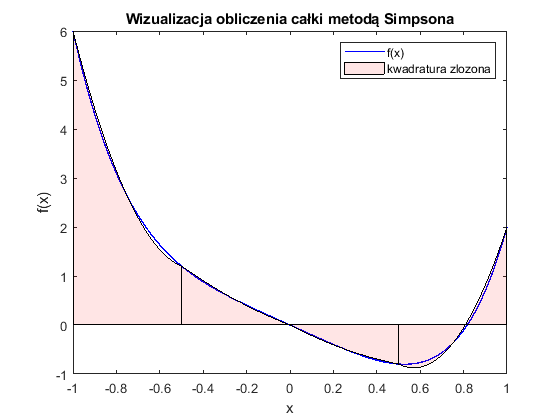

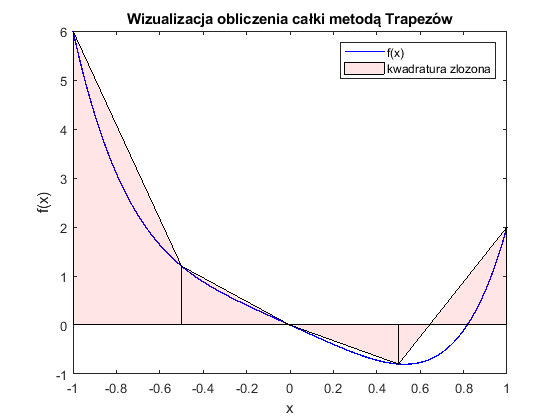

%%%%
title(axSimps,'Wizualizacja obliczenia całki metodą Simpsona')
title(axTrap,'Wizualizacja obliczenia całki metodą Trapezów')
if simpleVis==true
    legend(axSimps,'f(x)','kwadratura prosta','kwadratura zlozona')
    legend(axTrap,'f(x)','kwadratura prosta','kwadratura zlozona')
else
    legend(axSimps,'f(x)','kwadratura zlozona')
    legend(axTrap,'f(x)','kwadratura zlozona')
end